clc; clear; close all;

d =  5; % Number of Gram polynomial interpolation points
C = 27; % Number of continuation points
n_r = 6;

if(exist(['FC_data/A_d',num2str(d),'_C', num2str(C), '_r', num2str(n_r), '.mat']) == 0 | ...
   exist(['FC_data/Q_d',num2str(d),'_C', num2str(C),  '_r', num2str(n_r), '.mat']) == 0)
    disp('FC data not found. Generating FC operators... \n');
    generate_bdry_continuations(d, C, C, 12, 20, 4, ...
        256, n_r);
end

load(['FC_data/A_d',num2str(d),'_C', num2str(C), '_r', num2str(n_r), '.mat']);
load(['FC_data/Q_d',num2str(d),'_C', num2str(C),  '_r', num2str(n_r), '.mat']);

A = double(A);
Q = double(Q);

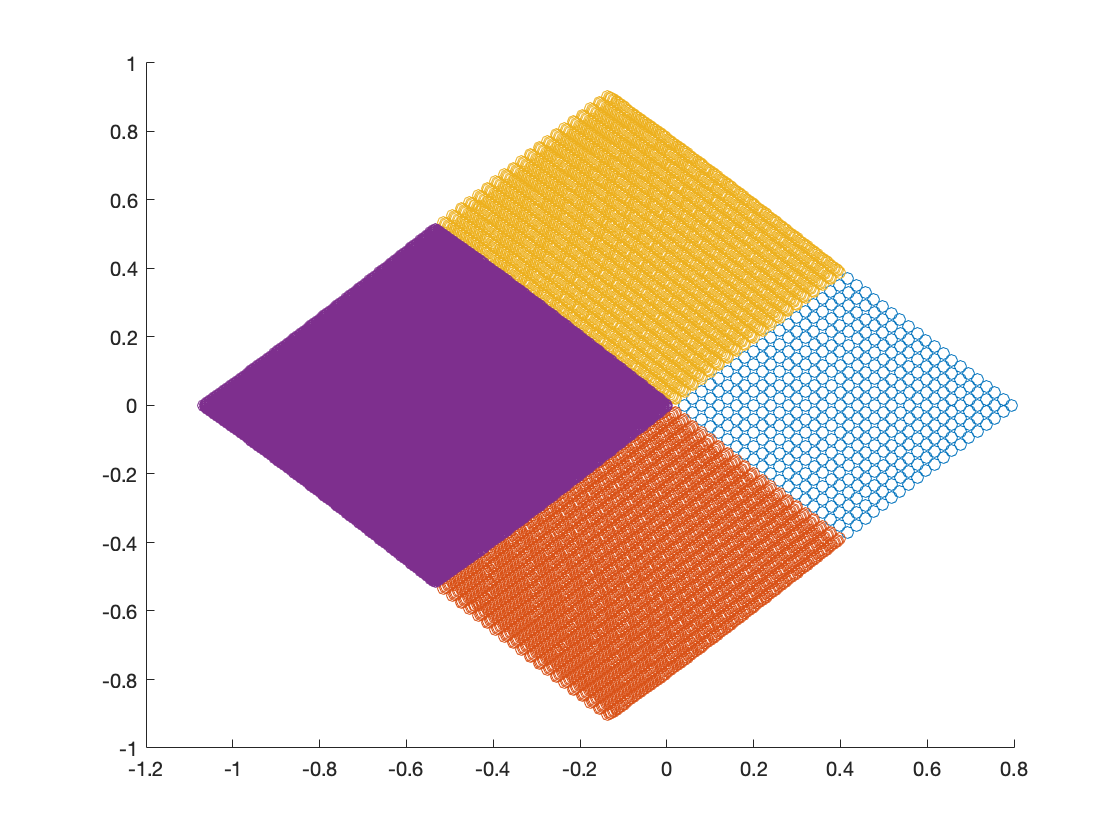

factor = 0;
n_C2 = 20*2^factor;
h = 0.029*(1/2)^factor;

C2_patch = construct_C2_patch(@(x, y) f(x, y), 0.4, 2*pi-0.4, 0, n_C2, n_C2);
[C2_fcont_patch_xi, C2_fcont_patch_eta, C2_fcont_patch_corner] = C2_patch.FC(C, n_r, d, A, Q, nan);

figure;
[X, Y] = C2_patch.xy_mesh();
scatter(X(:), Y(:));
hold on;
[X, Y] = C2_fcont_patch_xi.xy_mesh();
scatter(X(:), Y(:));
[X, Y] = C2_fcont_patch_eta.xy_mesh();
scatter(X(:), Y(:));
[X, Y] = C2_fcont_patch_corner.xy_mesh();
scatter(X(:), Y(:));

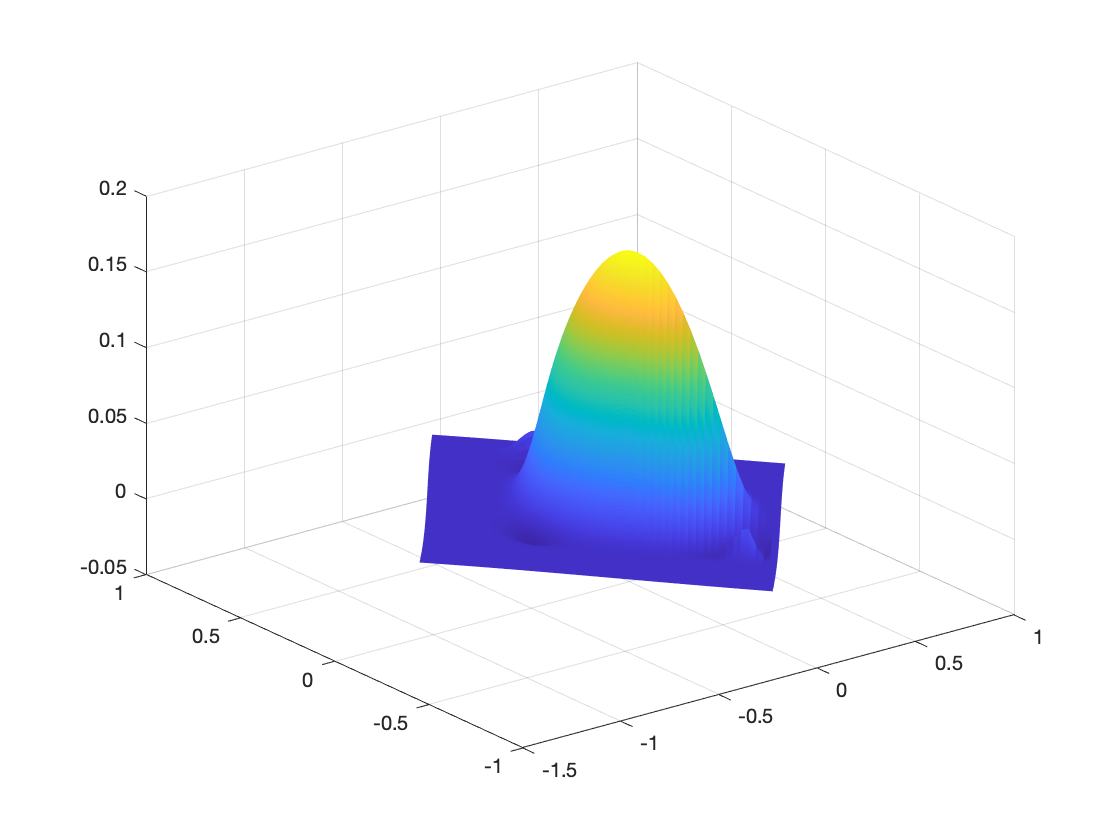


figure;
[X, Y] = C2_patch.xy_mesh();
s = surf(X, Y, C2_patch.f_XY);
s.EdgeColor = 'none';
hold on;

[X, Y] = C2_fcont_patch_xi.xy_mesh();
s = surf(X, Y, C2_fcont_patch_xi.f_XY);
s.EdgeColor = 'none';

[X, Y] = C2_fcont_patch_eta.xy_mesh();
s = surf(X, Y, C2_fcont_patch_eta.f_XY);
s.EdgeColor = 'none';

[X, Y] = C2_fcont_patch_corner.xy_mesh();
s = surf(X, Y, C2_fcont_patch_corner.f_XY);
s.EdgeColor = 'none';

[C2_bound_X, C2_bound_Y] = C2_patch.boundary_mesh_xy();
R = R_cartesian_mesh_obj(C2_fcont_patch_corner.x_min, C2_patch.x_max, C2_fcont_patch_xi.y_min, C2_fcont_patch_eta.y_max, h, C2_bound_X, C2_bound_Y);
R.interpolate_patch(C2_fcont_patch_xi, 8, false);

start first pass
construct nan map


R.interpolate_patch(C2_fcont_patch_eta, 8, false);

start first pass
construct nan map


R.interpolate_patch(C2_fcont_patch_corner, 8, false);

start first pass
construct nan map


R.fill_interior(@(x, y) f(x, y));

R.compute_fc_coeffs();

[R_X_err, R_Y_err, f_interpolation, interior_idx] = R.ifft_interpolation(R.h./2);

max(abs(f(R_X_err(interior_idx), R_Y_err(interior_idx))-f_interpolation(interior_idx)))

ans = 7.7762e-05

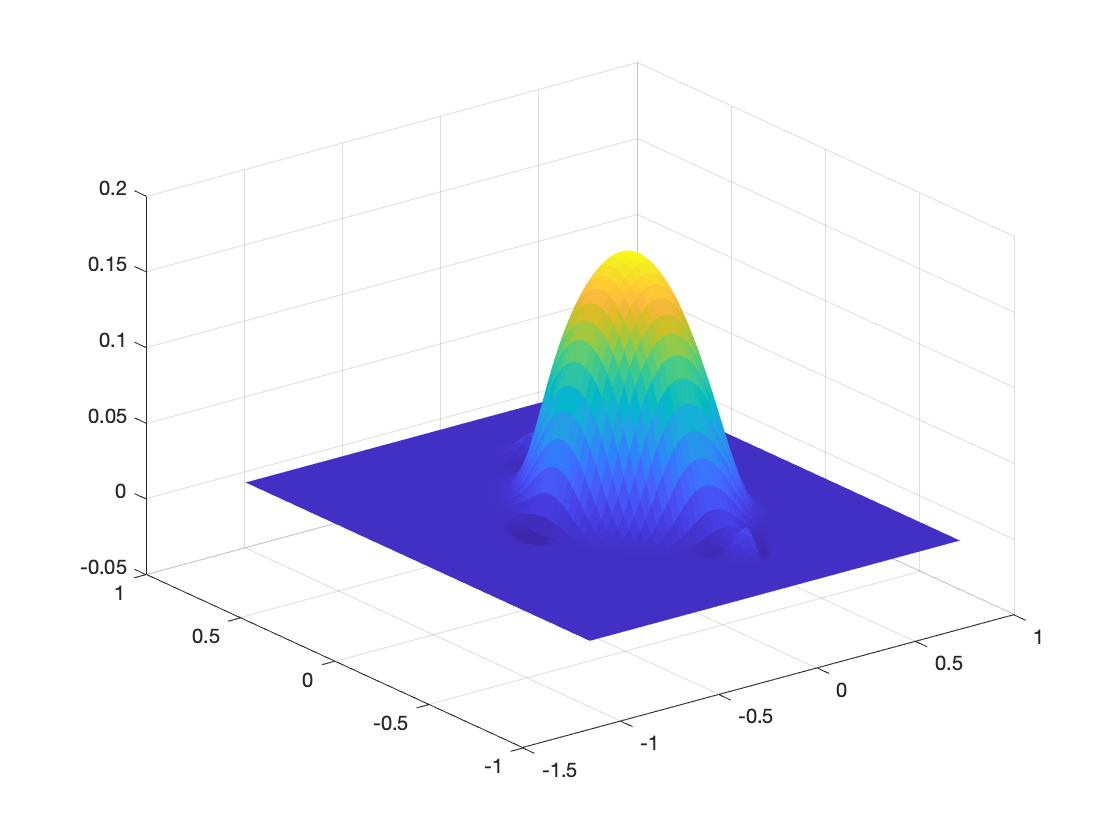

s =   Surface with properties:

       EdgeColor: 'none'
       LineStyle: '-'
       FaceColor: 'flat'
    FaceLighting: 'flat'
       FaceAlpha: 1
           XData: [64×66 double]
           YData: [64×66 double]
           ZData: [64×66 double]
           CData: [64×66 double]

  Show all properties



figure;
s = surf(R.R_X, R.R_Y, R.f_R);
s.EdgeColor = 'none'

function C2_patch = construct_C2_patch(f, theta_A, theta_B, theta_C, n_xi, n_eta)
    l_theta = @(theta) [2*sin(theta/2), -sin(theta)];
    
    l_A = @(xi) xi*(theta_A - theta_C) + theta_C;
    l_B = @(eta) eta*(theta_B - theta_C - 2*pi) + theta_C + 2*pi; % account for wrap around
    
    M_p = @(xi, eta) l_theta(l_A(xi)) + l_theta(l_B(eta)) - l_theta(theta_C);
    J = @(v) [theta_A*cos(v(1)*theta_A/2) (theta_B-2*pi)*cos((v(2)*(theta_B-2*pi)+2*pi)/2); -theta_A*cos(v(1)*theta_A) -(theta_B-2*pi)*cos(v(2)*(theta_B-2*pi)+2*pi)];
    
    xi_mesh = linspace(0, 1, n_xi+1);
    eta_mesh = linspace(0, 1, n_eta+1);
    
    [XI, ETA] = meshgrid(xi_mesh, eta_mesh);
    XY = M_p(XI(:), ETA(:));
    
    f_XY = reshape(f(XY(:, 1), XY(:, 2)), [n_eta+1, n_xi+1]);
    
    C2_patch = C2_patch_obj(M_p, J, n_xi, n_eta, 0, 1, 0, 1, f_XY, nan); % data associated with patch
end

function S_patch = construct_S_patch(f, theta_A, theta_B, h, n_xi, n_eta)
    l_theta = @(theta) [2*sin(theta/2), -sin(theta)];
    
    l_A = @(xi) (theta_B - theta_A)*xi + theta_A;
    nu = @(xi) [cos(l_A(xi)), cos(l_A(xi)/2)] ./ sqrt(cos(l_A(xi)).^2 + cos(l_A(xi)/2).^2);
    
    M_p_general = @(xi, eta, H) l_theta(l_A(xi)) + eta.*H.*nu(xi);
    % H is a function of h and n_eta
    
    theta_diff = theta_B - theta_A;
    J = @(v, H) [theta_diff*cos(l_A(v(1))/2)-v(2)*H*theta_diff*sin(l_A(v(1))), H*cos(l_A(v(1))); -1*theta_diff*cos(l_A(v(1)))-v(2)*H*theta_diff/2*sin(l_A(v(1))/2), H*cos(l_A(v(1))/2)];
    
    xi_mesh = linspace(0, 1, n_xi+1);
    eta_mesh = linspace(0, 1, n_eta+1);
    
    [XI, ETA] = meshgrid(xi_mesh, eta_mesh);
    XY = M_p_general(XI(:), ETA(:), h*n_eta);
    
    f_XY = reshape(f(XY(:, 1), XY(:, 2)), [n_eta+1, n_xi+1]);
    
    S_patch = S_patch_obj(M_p_general, J, n_xi, n_eta, 0, 1, 0, 1, f_XY, h, nan);
end

function f_y = f(x, y)
    r = sqrt(x.^2 + y.^2);
    f_y = zeros(size(x));
    f_y(r < 0.56) = exp(1./(1/0.56*r(r < 0.56).^2-0.56));
    f_y(r >= 0.56) = 0;
end

function f_y = f_smooth(x, y)
    f_y = zeros(size(x));
    interior_msk = x < 1 & x > 0 & y < 1 & y > 0;
    f_y(interior_msk) = exp(-1./(1-(2*x(interior_msk)-1).^2)).*exp(-1./(1-(2*y(interior_msk)-1).^2));
end